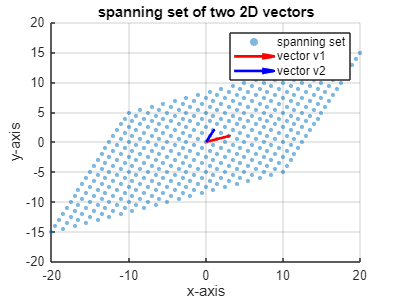

%plotting of span of two vector in plane 
%question-plot the span of v1=[3,1],v2=[1,2] in plane(2d).
%define the two 3D vectors
v1 =[3,1];
v2 =[1,2];
%define the orgin
orgin =[0,0];
%create a grid of scalar coefficients for the linear combinations
[s,t]= meshgrid(-5:0.5:5);
% compute the spanning set(linear combutions of v1 and v2)
x =s*v1(1)+t*v2(1);
y =s*v1(2)+t*v2(2);
%plot the spanning set (grid of points)
%figure;
scatter(x(:),y(:),10,'filled','markerFaceAlpha',0.5);
hold on;
%plot the original vectors
quiver(orgin(1),orgin(2),v1(1),v1(2),0,'r','LineWidth',2);
quiver(orgin(1),orgin(2),v2(1),v2(2),0,'b','LineWidth',2);
%set axis limits
xlim([-20,20]);
ylim([-20,20]);
%add labels and title
xlabel('x-axis');
ylabel('y-axis');
title('spanning set of two 2D vectors');
legend('spanning set','vector v1','vector v2');
grid on;
hold off;